# DSP Laboratory Report #3

Instructor: M.H. Shammakhi

Student: Dina Soltani Tehrani - 9523703

Last Update: May 5th

clc; clear; close all;
f0 = 500; %signal freq
fs = 10e3; %sampling freq
w0 = 2*pi*f0/fs; %digital freq
R = [0.8 0.9 0.99]; %the radius of the poles
a1 = -2*R*cos(w0);
a2 = R.^2;
G = (1-R).*((1-2*R*cos(2*w0)+R.^2).^(0.5)); % gain
w = zeros(1,5000);

## part 3-1-a

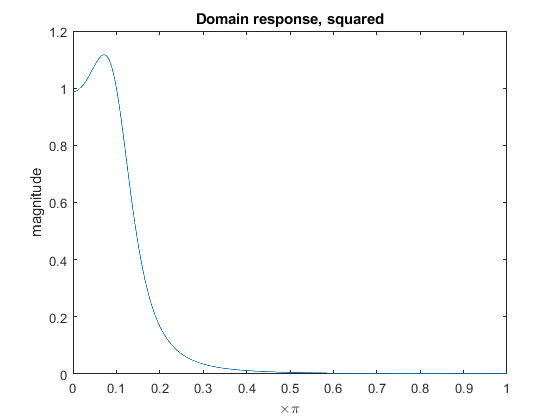

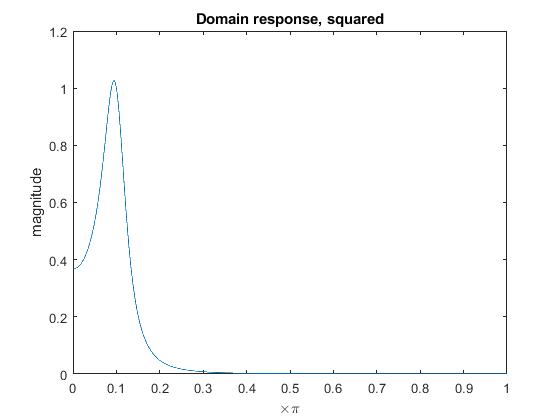

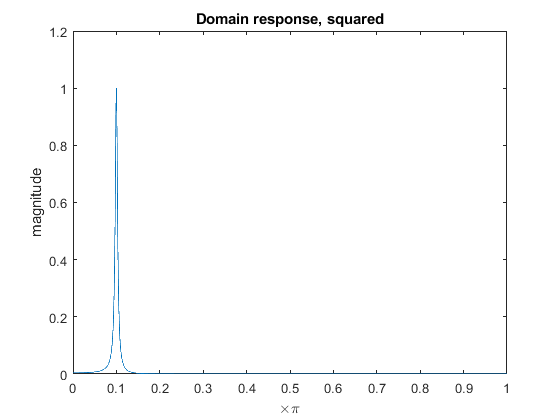

Hsq = zeros(1,5000); % domain response, has to become squared
for ii=1:3 % different R
    for jj = 0:fs/2-1 %500 point of w
       w(jj+1) = 2*pi*jj/fs; 
       Hsq(jj+1) = G(ii)^2/((1-2*R(ii)*cos(w(jj+1)-w0)+R(ii)^2)*(1-2*R(ii)*cos(w(jj+1)+w0)+R(ii)^2));
    end
    figure(ii);
    plot(linspace(0,1,length(Hsq)),Hsq);
    xlabel('\times\pi'); ylabel('magnitude'); title('Domain response, squared');
end

For cases other than R=0.99, the magnitude at the allowed frequency is more than one since the poles are located distant from the unity cicle. However, in the case of ahving R=0.99, the magnitude is almost equal to the unity.

## part 3-1-b

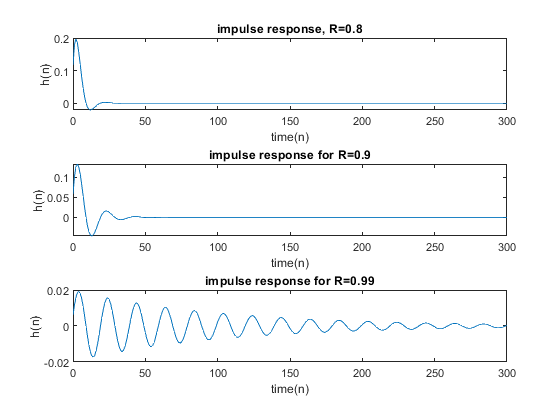

n = 0:300;
B1 = G(1); %R=0.8
A1 = [1 a1(1) a2(1)];
h = impz(B1,A1,n); % impulse response
figure(4);
subplot(3,1,1);
plot(n,h);
xlabel('time(n)'); ylabel('h(n)'); title('impulse response, R=0.8');
B2 = G(2); %R=0.9
A2 = [1 a1(2) a2(2)];
h = impz(B2,A2,n);
subplot(3,1,2);
plot(n,h);
xlabel('time(n)'); ylabel('h(n)'); title('impulse response for R=0.9');
B3 = G(3); %R=0.99
A3 = [1 a1(3) a2(3)];
h = impz(B3,A3,n);
subplot(3,1,3);
plot(n,h);
xlabel('time(n)'); ylabel('h(n)'); title('impulse response for R=0.99');

In this figure, the impulse response of the system was calculated and poltted regarding to the difference equation using the **impz** command. It can be deducted that the ripples increase with the poles getting closer to the unity circle. 

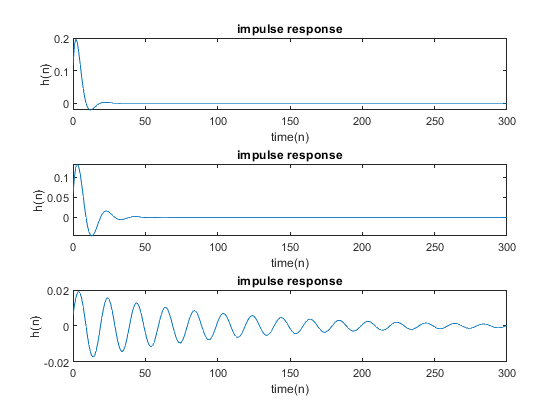

figure(5);
for ii=1:3
    h = (G(ii)/sin(w0))*(R(ii).^n).*sin(w0*n+w0);
    subplot(3,1,ii);
    plot(n,h);
    xlabel('time(n)'); ylabel('h(n)'); title('impulse response');   
end

The same system was represented using the formula of the system's impulse response. The plots seem to be the same in terms of an increase in the number of the ripples with the poles getting closer to theunity circle, quit exactly.

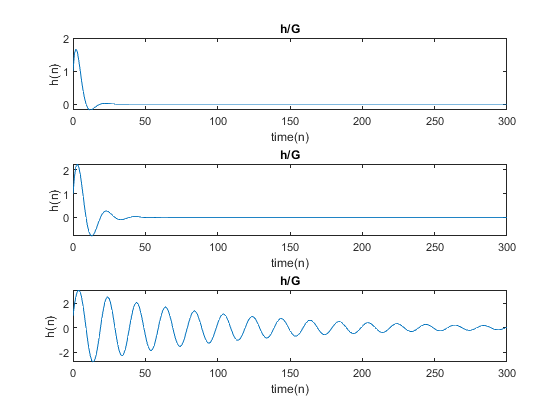

figure(6);
for ii=1:3
    h = (1/sin(w0))*(R(ii).^n).*sin(w0*n+w0);
    subplot(3,1,ii);
    plot(n,h);
    xlabel('time(n)'); ylabel('h(n)'); title('h/G');
end

The plots above are the same results without the gain factor, showing the changes in the location of the poles.

## part 3-1-c

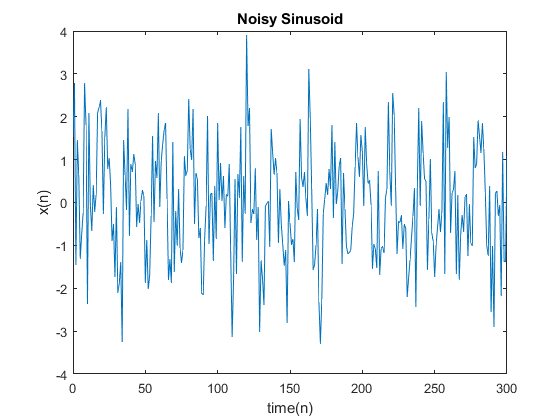

v = randn(1,length(n)); %noise
s = cos(w0*n);
x = v+s; %noisy Sinusoid
figure(7);
plot(n,x);
xlabel('time(n)'); ylabel('x(n)'); title('Noisy Sinusoid');

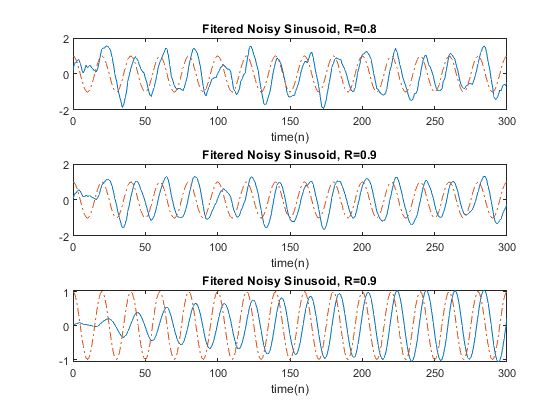

y = filter(B1,A1,x);
figure(8);
subplot(3,1,1);
plot(n,y);
hold on
plot(n,s,'-.');
xlabel('time(n)'); title('Fitered Noisy Sinusoid, R=0.8');

y = filter(B2,A2,x);
subplot(3,1,2);
plot(n,y);
hold on
plot(n,s,'-.');
xlabel('time(n)'); title('Fitered Noisy Sinusoid, R=0.9');

y = filter(B3,A3,x);
subplot(3,1,3);
plot(n,y);
hold on
plot(n,s,'-.');
xlabel('time(n)'); title('Fitered Noisy Sinusoid, R=0.9');

The created noisy signal which was plotted earlier, using the **rand** function to provide the **White Noise**, was filtered using the **filter** command and the designed filters with the location of the poles changing. With the poles getting closer to the unity circle, the designed filter becomes sharper, thus the resultant filter reaches to the steady response quicker.

## part 3-1-d

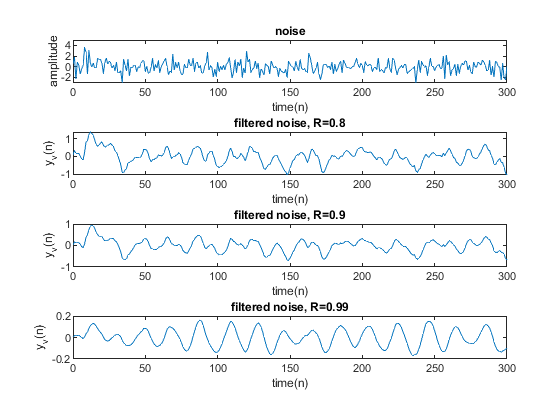

y_v1 = filter(B1,A1,v);
y_v2 = filter(B2,A2,v);
y_v3 = filter(B3,A3,v);

figure(9);
subplot(4,1,1);
plot(n,v);
xlabel('time(n)'); ylabel('amplitude'); title('noise');

subplot(4,1,2);
plot(n,y_v1);
xlabel('time(n)'); ylabel('y_v(n)'); title('filtered noise, R=0.8');

subplot(4,1,3);
plot(n,y_v2);
xlabel('time(n)'); ylabel('y_v(n)'); title('filtered noise, R=0.9');

subplot(4,1,4);
plot(n,y_v3);
xlabel('time(n)'); ylabel('y_v(n)'); title('filtered noise, R=0.99');

In this part, we separetedly filter the noise itself using the designed filters. It can be deducted that the filtered noise becomes more similar to a pure sinusoidal signal with the poles getting closer to the unity circle.

## part 3-1-e

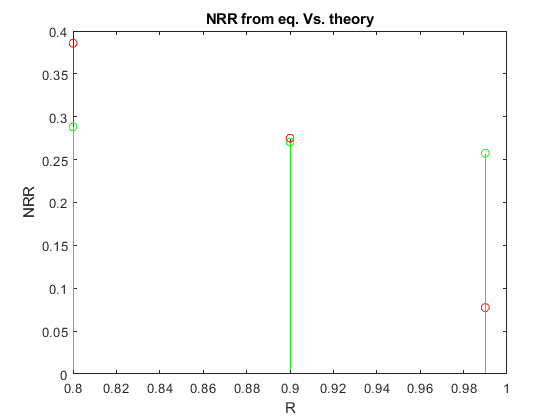

% NRR= delta(y_v)^2/delta(v)^2 --> equation
NRR1 = std(y_v1)/std(v); %= 0.3843
NRR2 = std(y_v2)/std(v); %= 0.2929
NRR3 = std(y_v3)/std(v); %= 0.1158
NRR= [ NRR1 , NRR2 , NRR3 ];
% NRR= (1+R^2)/[(1+R)*(1+2Rcos(w0)+r^2)] --> theory
NRR1_th = (1+R(1)^2)/((1+R(1))*(1+2*R(1)*cos(w0)+R(1)^2)); %= 0.2882
NRR2_th = (1+R(2)^2)/((1+R(2))*(1+2*R(2)*cos(w0)+R(2)^2)); %= 0.2705
NRR3_th = (1+R(3)^2)/((1+R(3))*(1+2*R(3)*cos(w0)+R(3)^2)); %=0.2576
NRR_th= [ NRR1_th , NRR2_th , NRR3_th ];
figure(10);
stem(R,NRR,'r')
hold on
stem(R,NRR_th, 'g')
xlabel('R'); ylabel('NRR'); title('NRR from eq. Vs. theory');

When using the 5-3 formula, the resultant h[n] comes as below:

- R=0.8   --> 0.2882

- R=0.9   --> 0.2705

- R=0.99 --> 0.2576

When running the program, the results for the NRR would be different, changing both with the time and the entry sequence. Therefore, the results provided here are for one running sequence:

- R=0.8   --> 0.3843

- R=0.9   --> 0.2929

- R=0.99 --> 0.1158

 The results are different as when using the formula, inputs would be considered static. On the other hand, the results would vary in time and the sequence. However, the decrease in the results in both cases seem to be crystal clear which means the closer the poles to the unity circle, the better the output in terms of the amplitude of the noise signal.

## Notch Filter

### part 3-2-a-a

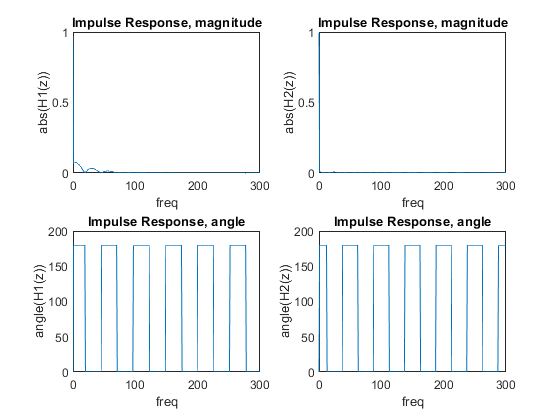

% H1
B4 = [0.969531 -1.932772 0.969531];
A4 = [1 -1.923772 0.939063];
% H2
B5 = [0.996088 -1.976468 0.996088];
A5 = [1 -1.976468 0.992177];
n = 0:300;
H1 = impz(B4,A4,n);
figure(11);
subplot(2,2,1); plot(n,abs(H1));
xlabel('freq'); ylabel('abs(H1(z))'); title('Impulse Response, magnitude');
subplot(2,2,3); plot(n,(180/pi)*angle(H1));
xlabel('freq'); ylabel('angle(H1(z))'); title('Impulse Response, angle');
H2 = impz(B5,A5,n);
subplot(2,2,2); plot(n,abs(H2));
xlabel('freq'); ylabel('abs(H2(z))'); title('Impulse Response, magnitude');
subplot(2,2,4); plot(n,(180/pi)*angle(H2));
xlabel('freq'); ylabel('angle(H2(z))'); title('Impulse Response, angle');

### part 3-2-a-b

f1 = 4;
f2 = 8;
f3 = 12;
fs2 = 400;
t1 = 0:1/fs2:2-1/fs2;
t2 = 2:1/fs2:4-1/fs2;
t3 = 4:1/fs2:6-1/fs2;
x2 = [cos(2*pi*f1*t1),cos(2*pi*f2*t2),cos(2*pi*f3*t3)];

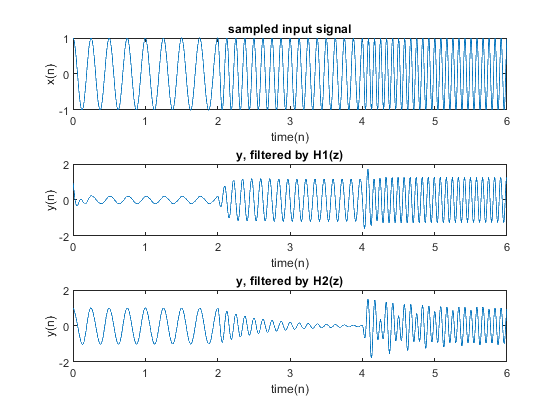

figure(12);
subplot(3,1,1); plot(linspace(0,6,length(x2)),x2);
xlabel('time(n)'); ylabel('x(n)'); title('sampled input signal');
y = filter(B4,A4,x2);
subplot(3,1,2); plot(linspace(0,6,length(y)),y);
xlabel('time(n)'); ylabel('y(n)'); title('y, filtered by H1(z)');
y = filter(B5,A5,x2);
subplot(3,1,3); plot(linspace(0,6,length(y)),y);
xlabel('time(n)'); ylabel('y(n)'); title('y, filtered by H2(z)');

The first filter has high bandwidth and short time response. However, the second filter has narrow bandwidth but has long time response. This can be deducted from the figures above.

%% part 3-2-f
% dont know how to plot H1(f) and H2(f) at f=0:20
%% part 3-2-g
%% part 3-2-h

## Peak Filter

### part 3-2-b-a

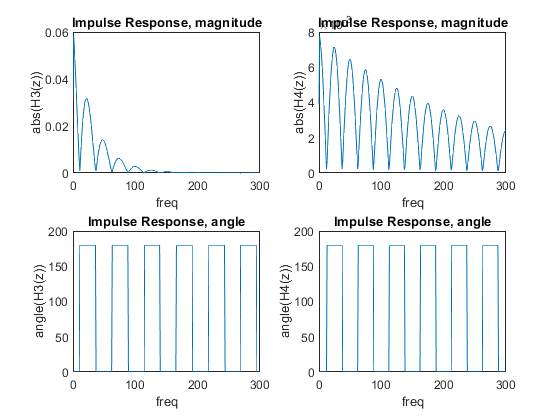

B6 = [0.030469 0 -0.030469];
A6 = [1 -1.923772 0.939063];
B7 = [0.003912 0 -0.003912];
A7 = [1 -1.976468 0.992177];
n = 0:300;
H3 = impz(B6,A6,n);
figure(13);
subplot(2,2,1); plot(n,abs(H3));
xlabel('freq'); ylabel('abs(H3(z))'); title('Impulse Response, magnitude');
subplot(2,2,3); plot(n,(180/pi)*angle(H3));
xlabel('freq'); ylabel('angle(H3(z))'); title('Impulse Response, angle');
H4 = impz(B7,A7,n);
subplot(2,2,2); plot(n,abs(H4));
xlabel('freq'); ylabel('abs(H4(z))'); title('Impulse Response, magnitude');
subplot(2,2,4); plot(n,(180/pi)*angle(H4));
xlabel('freq'); ylabel('angle(H4(z))'); title('Impulse Response, angle');

### part 3-2-b-b

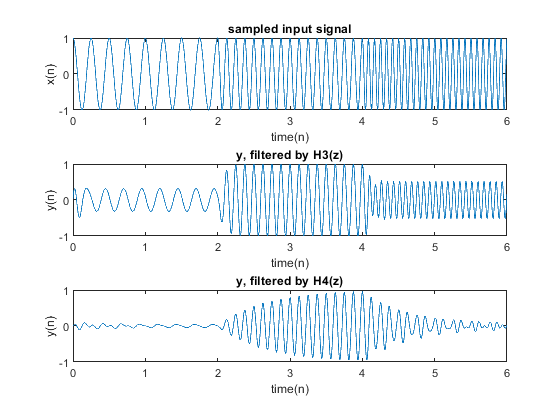

figure(14);
subplot(3,1,1); plot(linspace(0,6,length(x2)),x2);
xlabel('time(n)'); ylabel('x(n)'); title('sampled input signal');
y = filter(B6,A6,x2);
subplot(3,1,2); plot(linspace(0,6,length(y)),y);
xlabel('time(n)'); ylabel('y(n)'); title('y, filtered by H3(z)');
y = filter(B7,A7,x2);
subplot(3,1,3); plot(linspace(0,6,length(y)),y);
xlabel('time(n)'); ylabel('y(n)'); title('y, filtered by H4(z)');

It is deducted that both of the filters have kept the mid freq while eliminating the higher and the lower frequencies. 